clear
syms A x x0 s p p0 h

s=1;
A=1/sqrt(s*sqrt(pi));
h=1;
x0=1;
p0=0;


%A is amplitude
%x0 is the center 
%s is standard deviation, half the width of the function where G=A/sqrt(e)

G=A*exp(-(x-x0)^2/(2*s^2)); %Gaussian

Y=exp(1i*p0*x/h); %

Yx=G*Y; %Gaussian wave packet of position

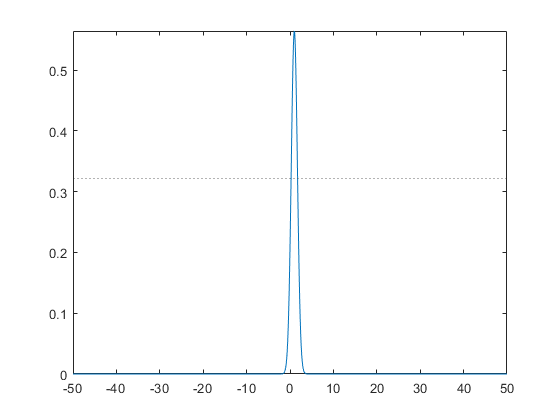


sp=1/s; %sigma p = h/sigma x  uncertainties of the probability amplitudes

Yp=(s.^2/(pi*h^2))^(1/4)*exp(-(p-p0)^2/(2*sp^2)); %Gaussian wave packet of momentum
Px=Yx*conj(Yx); %Probability amplitude of position
Py=Yp*conj(Yp); %Probability amplitude of momentum


fplot(Px,[-50 50])
hold on 
yline(A/sqrt(exp(1))/sqrt(2),':'); % sigma x (uncertainty of position) is the half width of this (=A/sqrt(e))
hold off

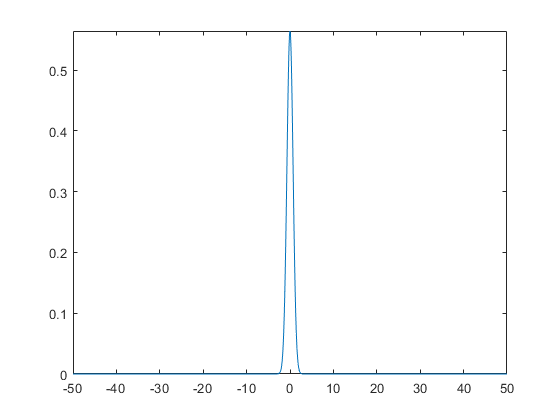

fplot(Py,[-50 50])

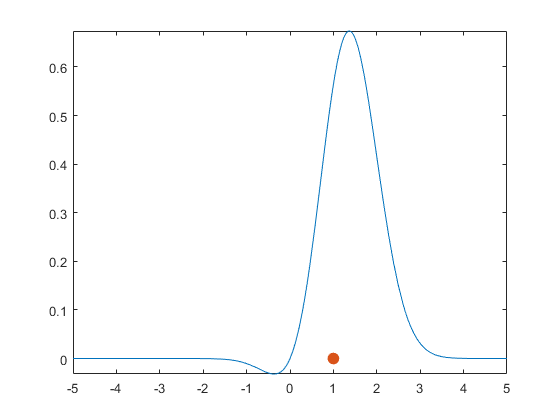

fplot(x*Px) %Average value of the position is the integral of this
ave=int(x*Px,-inf,inf); %average position
hold on 
plot(ave,0,'.','MarkerSize',30)